### Motivation

In a world of ever-increasing global automation, the requirement for robust, reliable, Real-Time Data Acquisition is greater than ever before. Real-time data acquisition is crucial in many applications such as UAV flight control, self driving cars, object detection, robitics and so on.

### **Objective**

To discuss about the tools and processes available for image/signal acquisition and how to process them using MATLAB/simulink.

### **Image/signal Acquisition from ios/android device**

This example will show how to use a mobile device to acquire real-time signal/image and process them using MATLAB.

####  Connecting ios/android device with MATLAB

- Install MATLAB support package for ios/android devices

- Install MATLAB mobile on phone

- Both in MATLAB mobile and MATLAB on your computer sign in with same account

- Open the MATLAB mobile app and select the sensor of which we want to get data. In the setting we must turn on the sensor access.

- In MATLAB mobile settings we have to select stream to MATLAB

- You can get image/video, acceleration, Magnetic field, orientation, angular velocity and position data from the cell phone.

- In MATLAB desktop we have to create a mobile device class to access the sensors of the device

clear
clc
m = mobiledev

m = mobiledev with properties:

                      Device: 'iPhone - Michael's iPhone (2)'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
        AvailableMicrophones: {'iPhone Microphone Back' 'iPhone Microphone Bottom' 'iPhone Microphone Front'}
          SelectedMicrophone: 'iPhone Microphone Back'

            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0
           MicrophoneEnabled: 0
Show all properties

There are several methods in the mobiledev class from which we can access diffrent sensor data. Methods for class mobiledev-

             accellog     camera       disp         mobiledev    poslog       

             angvellog    discardlogs  magfieldlog  orientlog

#### Getting access of the phone camera

Need to create a camera object using the method camera.

c = camera(m,"back")

c =   Camera with properties:

                    Name: "back"
    AvailableResolutions: {'640x480'  '1280x720'}
              Resolution: '640x480'
               Autofocus: 'off'
                   Flash: 'off'


Now, let's take a snapshot using the camera object c and the phone camera

img = snapshot(c, 'manual');

Let's see the captured image using imshow

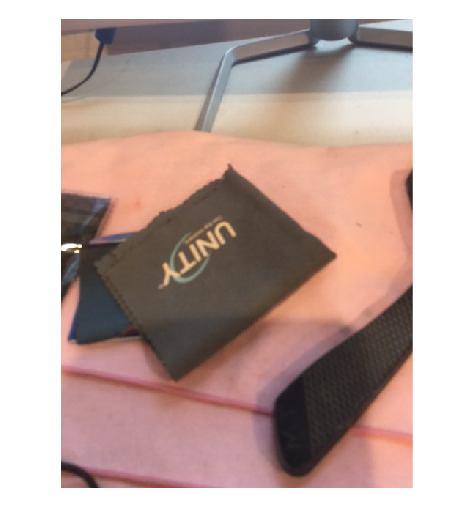

imshow(img)

If we want to convert it to grascale image and detect it's edges we can do it following the code below-

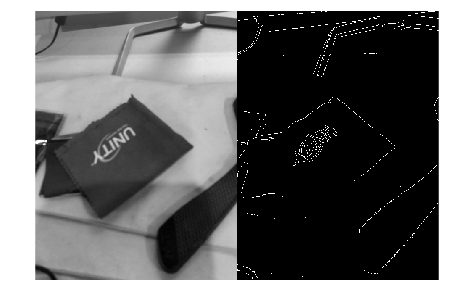

img = im2gray(img);
img1 = edge(img);
imshowpair(img, img1, 'montage')

#### Getting acceleration data from phone

Follow the instructions discussed in  Connecting ios/android device with MATLAB

- Now turn the acceration on in the MATLAB mobile app

- Again create a mobile device class to access the sensors of the device

clear
m = mobiledev

m = mobiledev with properties:

                      Device: 'iPhone - Michael's iPhone (2)'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
        AvailableMicrophones: {'iPhone Microphone Back' 'iPhone Microphone Bottom' 'iPhone Microphone Front'}
          SelectedMicrophone: 'iPhone Microphone Back'

            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0
           MicrophoneEnabled: 0
Show all properties

- In the object we can see that only AccelerationsensorEnabled = 1, all the other sensors value is 0. This is  because in our MATLAB mobile app we only turned on the acceleration ssensor.

- Click the start button to start recording the acceleration.

- There are several methods in the mobiledev class from which we can access diffrent sensor data. Methods for class mobiledev-

             accellog     camera       disp         mobiledev    poslog       

             angvellog    discardlogs  magfieldlog  orientlog  

#### Getting the recorded acceleration from phone

[a,t] = m.accellog

a =    -1.3697    7.3388    6.5408
   -1.3255    6.6995    6.6370
   -0.7814    6.6588    6.7619
    0.2238    6.4118    7.9827
    1.2342    5.4144    8.2893
    1.8157    4.9837    8.3766
    1.1355    4.1723    8.9723
    0.7471    3.5764    8.2252
    0.1260    2.9070    8.7568
    0.0247    3.1089    9.2325


t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


Now let's plot the acceleration signal

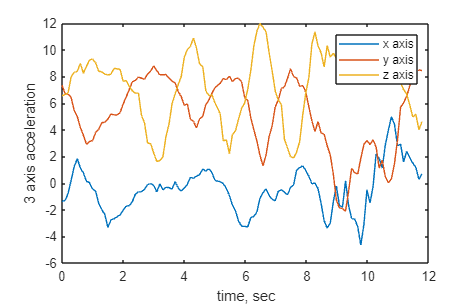

plot(t, a)
xlabel('time, sec')
ylabel('3 axis acceleration')
legend('x axis', 'y axis', 'z axis')

Calculating the sampling frequency of the signal

N = length(a) % total number of samples in the signal

N = 118

fs = N/max(t)

fs = 10.0255

In MATLAB mobile the frequency of the acceleration signal was 10 Hz which matches with our calculated fequency.

#### **Measuring tilt angle using 3 axis acceleration data**

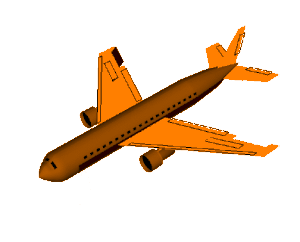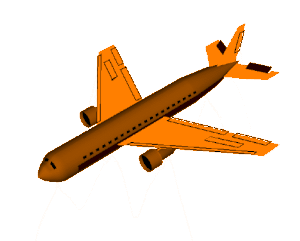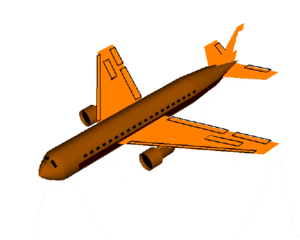

**      Roll                                        Pitch                                 Yaw**

(horizontal orientation)          (vertical orientation)

We want to measure the roll and pitch angles. Foe measuring the yaw, we may need another sensor data.

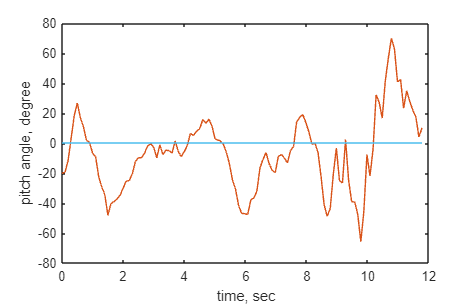

x = a(:, 1);
y = a(:, 2);
z = a(:, 3);
pitch = 180 * atan(x/sqrt(y.^2+z.^2));
roll = 180 * atan(y/sqrt(x.^2+z.^2));

plot(t, pitch)
xlabel('time, sec');
ylabel('pitch angle, degree')

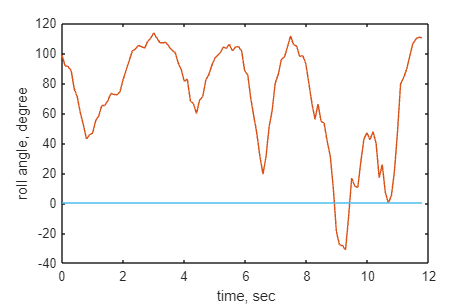


plot(t, roll)
xlabel('time, sec');
ylabel('roll angle, degree')